s=tf('s');
G=zpk(2/(s*(2*s^2+8*s+6)))


G =
 
        1
  -------------
  s (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



FT=feedback(G,1)


FT =
 
                  1
  ----------------------------------
  (s+3.148) (s^2 + 0.8521s + 0.3177)
 
Continuous-time zero/pole/gain model.



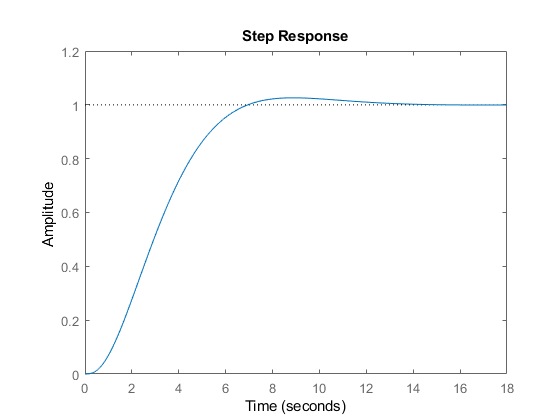

step(FT)

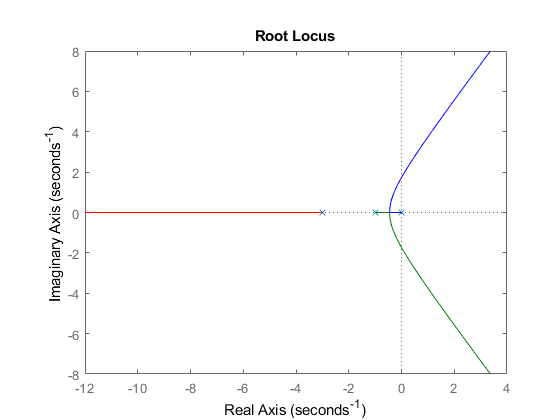

rlocus(G)

%%formulas
zeta=0.4;
%zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))
mp=exp((-zeta*pi)/(sqrt(1-zeta^2)))

mp = 0.2538

wn=1.4; %%termino independiente de la FT
ts=4/zeta*wn

ts = 14

sigma=zeta*wn 

sigma = 0.5600

wd=wn*sqrt(1-zeta^2)

wd = 1.2831

sx=-sigma+wd*i

sx = -0.5600 + 1.2831i

Gx=2/(sx*(2*sx^2+8*sx+6))

Gx = -0.1613 + 0.1023i

z=sigma;
p=z+5;
cx=(sx+z)/(sx+p);
kc=1/(abs(Gx)*abs(cx))

kc = 21.0618

c=zpk(-z,-p,kc)


c =
 
  21.062 (s+0.56)
  ---------------
     (s+5.56)
 
Continuous-time zero/pole/gain model.



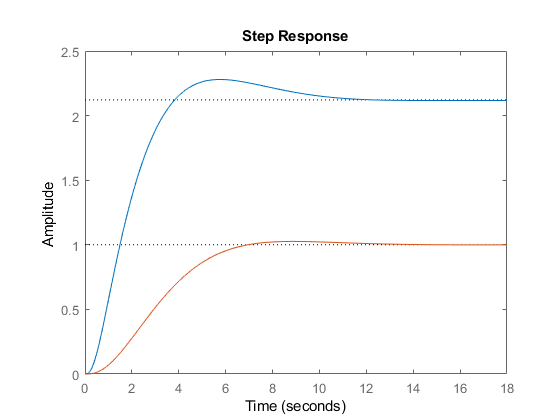

step(c*FT,FT)